# EXAMPLES OF CATEGORICAL DATA ANALYSIS

examples_categorical shows a series of analysis of regression datasets Copyright 2008-2017. Written by FSDA team

## Correpondence analysis of the smoke data (1)

Input is the contingency table

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                Scores               CntrbPnt2In           CntrbDim2In    
          ___________________    ___________________    __________________

    r1 

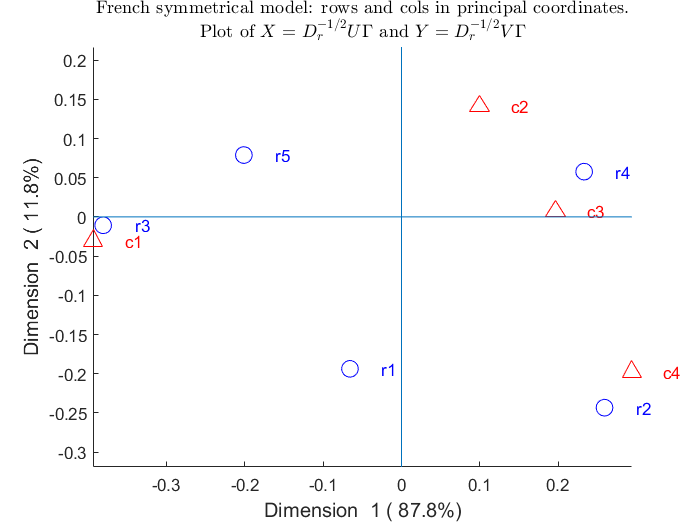

load smoke
N=crosstab(X(:,1),X(:,2));
% All rows and columns of n are active points (no supplementary unit)
out=CorAna(N);

## Correpondence analysis of the smoke data (2)

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                              Scores               CntrbPnt2In           CntrbDim2In    
                        ___________________    ___________________    __________________

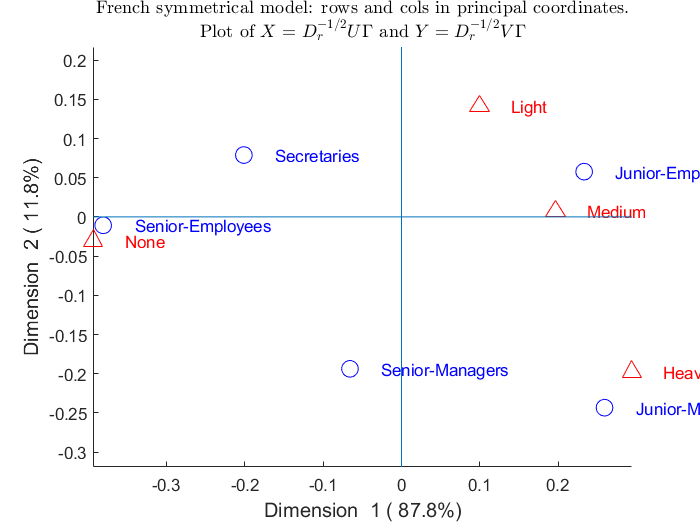

load smoke
N=crosstab(X(:,1),X(:,2));
% Input is the contingency table, labels for rows and columns are supplied
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns);

## Correpondence analysis of the smoke data (3)

Summary
               Singular_value            Inertia              Accounted_for           Cumulative    
             __________________    ____________________    ____________________    _________________

    dim_1     0.282218954141421      0.0796475380766772       0.905071583690946    0.905071583690946
    dim_2    0.0912953472692533     0.00833484043301356      0.0947126227964085    0.999784206487354
    dim_3    0.0043577659936195    1.89901244551465e-05    0.000215793512645189                    1

ROW POINTS
Results for dimension: 1
                              Scores             CntrbPnt2In           CntrbDim2In   
                        __________________    __________________    _______________

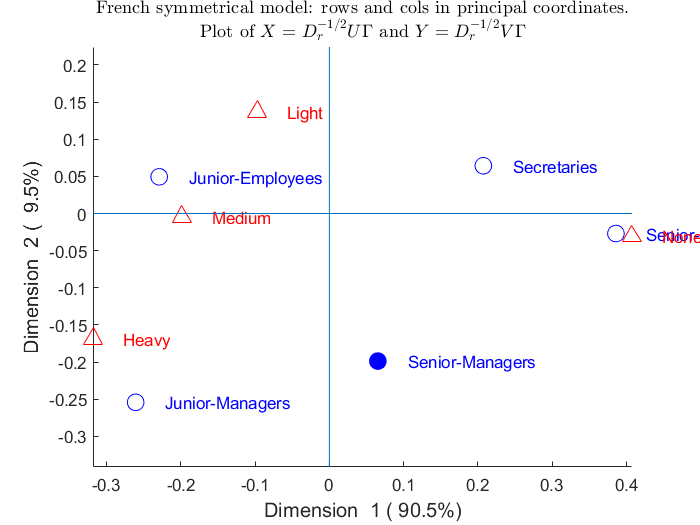

load smoke
N=crosstab(X(:,1),X(:,2));
% Input is the contingency table, first row is used as supplementary point
% In this case the list of supplementary units is passed using field .r
% passed as non negative number  which identifies  the row to use as
% supplementary point.
Sup=struct;
Sup.r=1;
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (4)

Summary
               Singular_value            Inertia            Accounted_for         Cumulative    
             __________________    ___________________    _________________    _________________

    dim_1     0.193474151145677     0.0374322471615404    0.878895803940006    0.878895803940006
    dim_2    0.0718180898302717    0.00515783802686898    0.121104196059994                    1

ROW POINTS
Results for dimension: 1
                              Scores             CntrbPnt2In          CntrbDim2In   
                        __________________    _________________    _________________

    Senior-Managers     -0.223658310022125    0.118548258431371    0.520447906765912
    Junior-Em

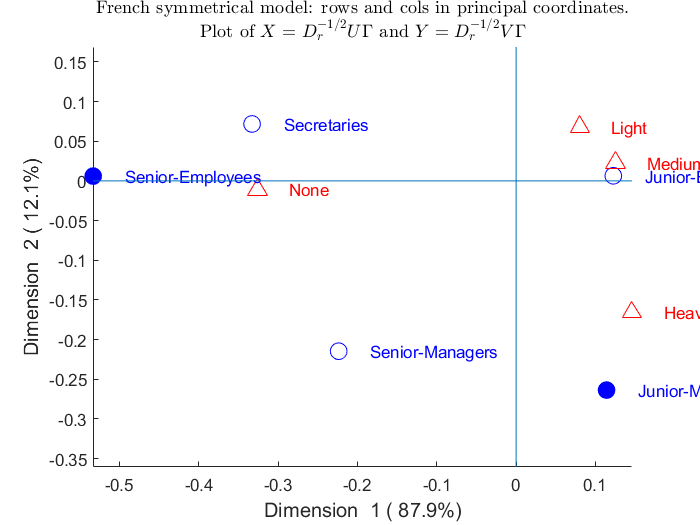

load smoke
N=crosstab(X(:,1),X(:,2));
% Input is the contingency table, rows 2 and 3 are used as supplementary
% points.
% In this case the list of supplementary units is passed using field .r
% passed as vector of non negative numbers
Sup=struct;
Sup.r=[2,3];
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (5)

Summary
               Singular_value            Inertia            Accounted_for         Cumulative    
             __________________    ___________________    _________________    _________________

    dim_1     0.193474151145677     0.0374322471615404    0.878895803940006    0.878895803940006
    dim_2    0.0718180898302717    0.00515783802686898    0.121104196059994                    1

ROW POINTS
Results for dimension: 1
                              Scores             CntrbPnt2In          CntrbDim2In   
                        __________________    _________________    _________________

    Senior-Managers     -0.223658310022125    0.118548258431371    0.520447906765912
    Junior-Em

load smoke
N=crosstab(X(:,1),X(:,2));
% Input is the contingency table, 2 rows are used as supplementary poitns.
% In this case the list of supplementary units is passed using field .r
% passed as a cell of characters.
Sup=struct;
Sup.r=labels_rows(2:3);
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (6)

The input is the original data matrix.

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                              Scores               CntrbPnt2In           CntrbDim2In    
                        ___________________    ___________________    __________________

load smoke
out=CorAna(X,'Lr',labels_rows,'Lc',labels_columns,'datamatrix',true);

## Correpondence analysis of the smoke data (7)

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                              Scores               CntrbPnt2In           CntrbDim2In    
                        ___________________    ___________________    __________________

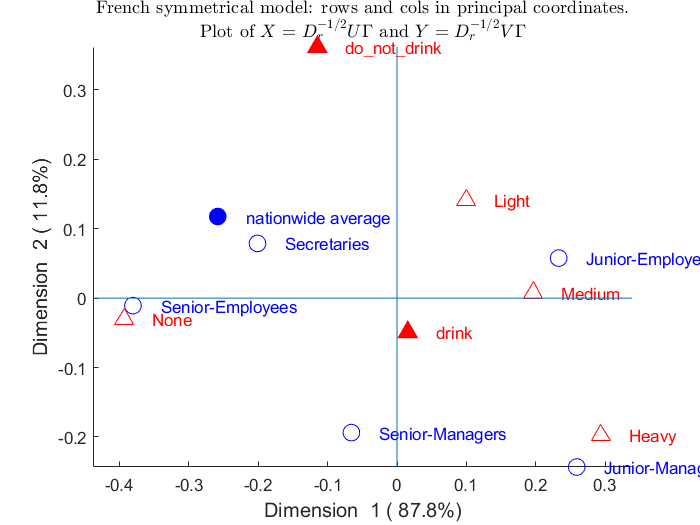

load smoke
% In this section we reproduce Figure 3.6 of Greenacre, (1984). Theory and
% Applications of Correspondence Analysis p. 71.
% The input is the original data matrix.
% Supplementary rows and columns are passed as tables.
supr=[0.42 0.29 0.20 0.09];
Nsupr=array2table(supr,'RowNames',{'nationwide average'},'VariableNames',labels_columns);
supc=[0 11; 1 17; 5 46; 10 78; 7 18];
Nsupc=array2table(supc,'RowNames',labels_rows,'VariableNames',{'do_not_drink' 'drink'});
Sup.r=Nsupr;
Sup.c=Nsupc;
out=CorAna(X,'Lr',labels_rows,'Lc',labels_columns,'datamatrix',true,'Sup',Sup);

## Correpondence analysis of the smoke data (8)

In this section we explore options inside input structure plots

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                              Scores              CntrbPnt2In           CntrbDim2In    
                        __________________    ___________________    __________________

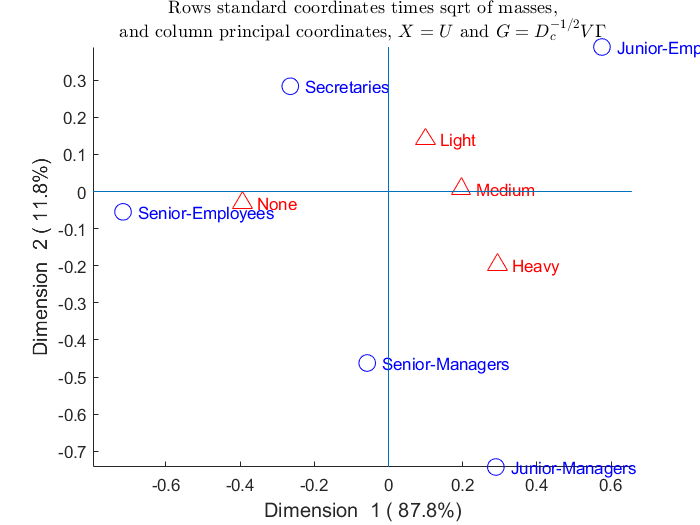

load smoke
N=crosstab(X(:,1),X(:,2));
plots=struct;
plots.alpha='rowprincipal';
plots.alpha='colprincipal';
plots.alpha='bothprincipal';
plots.alpha='rowgab';
plots.alpha='colgab';
plots.alpha='rowgreen';
plots.alpha='colgreen';
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'plots',plots);

## Correspondence analysis of the children dataset (1)

The data used here are a contingency table that summarizes the answers given by different categories of people to the following question : according to you, what are the reasons that can make hesitate a woman or a couple to have children? The input N is a matrix with 18 rows and 8 columns. Rows represent the the different reasons mentioned, columns represent the different categories (education, age) people belong to. Active rows (rows 1:14) : Rows that are used during the correspondence analysis. Supplementary rows (rows 15:18): the coordinates of these rows will be predicted using the CA informations and parameters obtained with active rows/columns Active columns (columns 1:5): columns that are used for the correspondence analysis. Supplementary columns (6:8): the coordinates of these columns will be predicted. Source Traitements Statistiques des Enquêtes (D. Grangé, L. Lebart, eds.) Dunod, 1993

Summary
               Singular_value            Inertia            Accounted_for         Cumulative    
             __________________    ___________________    _________________    _________________

    dim_1     0.188152966830548     0.0354015389271374     0.57042856025284     0.57042856025284
    dim_2     0.114519584527902     0.0131147352404433    0.211319049058871    0.781747609311711
    dim_3    0.0854465563954348    0.00730111399983822    0.117643584809728    0.899391194121439
    dim_4     0.079018437384334    0.00624391344666192    0.100608805878562                    1

ROW POINTS
Results for dimension: 1
                            Scores               CntrbPnt2In             CntrbDim2In    
                     

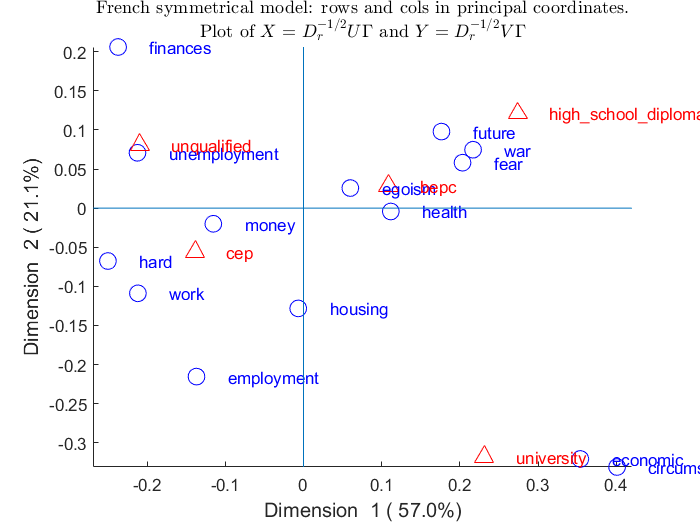

N=[51	64	32	29	17	59	66	70;
    53	90	78	75	22	115	117	86;
    71	111	50	40	11	79	88	177;
    1	7	5	5	4	9	8	5;
    7	11	4	3	2	2	17	18;
    7	13	12	11	11	18	19	17;
    21	37	14	26	9	14	34	61;
    12	35	19	6	7	21	30	28;
    10	7	7	3	1	8	12	8;
    4	7	7	6	2	7	6	13;
    8	22	7	10	5	10	27	17;
    25	45	38	38	13	48	59	52;
    18	27	20	19	9	13	29	53;
    35	61	29	14	12	30	63	58;
    2	4	3	1	4	nan  nan	nan	  ;
    2	8	2	5	2	nan  nan	nan;
    1	5	4	6	3	nan  nan	nan;
    3	3	1	3	4	nan  nan	nan];
% rowslab = cell containing row labels
rowslab={'money','future','unemployment','circumstances',...
    'hard','economic','egoism','employment','finances',...
    'war','housing','fear','health','work','comfort','disagreement',...
    'world','to_live'};
% colslab = cell containing column labels
colslab={'unqualified','cep','bepc','high_school_diploma','university',...
    'thirty','fifty','more_fifty'};

tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);
% Extract just active rows
Nactive=tableN(1:14,1:5);
% Correspondence analysis
out=CorAna(Nactive);

## Correspondence analysis of the children dataset (2)

Supplementary rows and columns are passed as table

Summary
               Singular_value            Inertia            Accounted_for         Cumulative    
             __________________    ___________________    _________________    _________________

    dim_1     0.188152966830548     0.0354015389271374     0.57042856025284     0.57042856025284
    dim_2     0.114519584527902     0.0131147352404433    0.211319049058871    0.781747609311711
    dim_3    0.0854465563954348    0.00730111399983822    0.117643584809728    0.899391194121439
    dim_4     0.079018437384334    0.00624391344666192    0.100608805878562                    1

ROW POINTS
Results for dimension: 1
                            Scores               CntrbPnt2In             CntrbDim2In    
                     

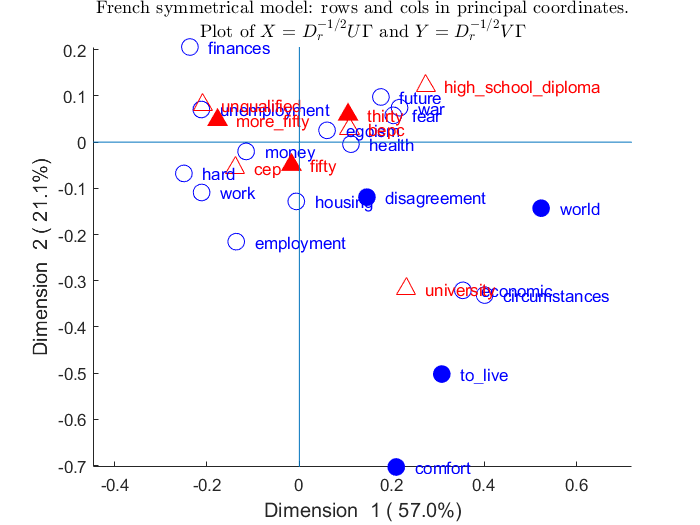

Nsupr=tableN(15:18,1:5);
Nsupc=tableN(1:14,6:8);
Sup=struct;
Sup.r=Nsupr;
Sup.c=Nsupc;
out=CorAna(Nactive,'Sup',Sup);

## Correspondence analysis of the housetasks dataset (1)

The data are a contingency table containing 13 housetasks and their repartition in the couple: rows are the different tasks, colums values are the frequencies of the tasks done: "by the wife only", "alternatively by the husband only" or "jointly", As the above contingency table is not very large, with a quick visual examination it can be seen that: The house tasks Laundry, Main_Meal and Dinner are dominant in the column Wife Repairs are dominant in the column Husband Holidays are dominant in the column Jointly

Summary
              Singular_value           Inertia           Accounted_for         Cumulative    
             _________________    _________________    _________________    _________________

    dim_1    0.736810209527852    0.542889284864477    0.486922212366375    0.486922212366375
    dim_2    0.667085272780942    0.445002761161224    0.399126921482452    0.886049133848827
    dim_3    0.356438540746555    0.127048433329534    0.113950866151174                    1

ROW POINTS
Results for dimension: 1
                        Scores              CntrbPnt2In           CntrbDim2In    
                  __________________    ___________________    __________________

    Laundry   

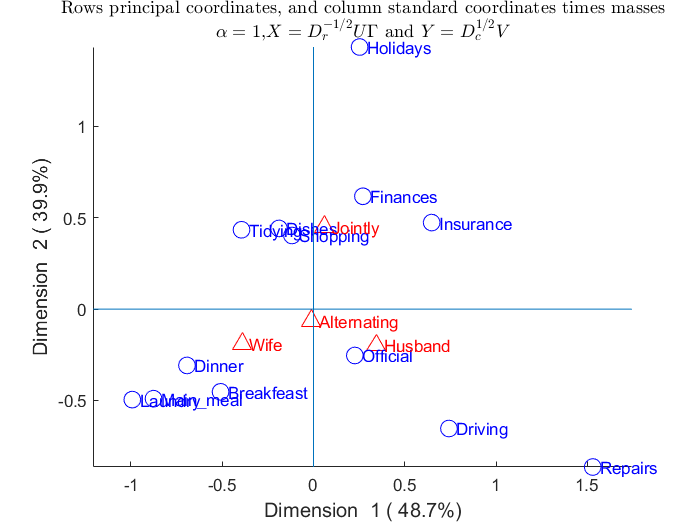

N=[156	14	2	4;
    124	20	5	4;
    77	11	7	13;
    82	36	15	7;
    53	11	1	57;
    32	24	4	53;
    33	23	9	55;
    12	46	23	15;
    10	51	75	3;
    13	13	21	66;
    8	1	53	77;
    0	3	160	2;
    0	1	6	153];
rowslab={'Laundry' 'Main_meal' 'Dinner' 'Breakfeast' 'Tidying' 'Dishes' ...
    'Shopping' 'Official' 'Driving' 'Finances' 'Insurance'...
    'Repairs' 'Holidays'};
colslab={'Wife'	'Alternating'	'Husband'	'Jointly'};
tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);

% In this section we explore options inside input structure plots
plots.alpha='colgreen';
plots.alpha='rowprincipal';
plots.alpha='rowgab';
out=CorAna(tableN,'plots',plots);

## Correspondence analysis of the housetasks dataset (2)

`Option plots supplied as input structure and alpha as numeric`

Summary
              Singular_value           Inertia           Accounted_for         Cumulative    
             _________________    _________________    _________________    _________________

    dim_1    0.736810209527852    0.542889284864477    0.486922212366375    0.486922212366375
    dim_2    0.667085272780942    0.445002761161224    0.399126921482452    0.886049133848827
    dim_3    0.356438540746555    0.127048433329534    0.113950866151174                    1

ROW POINTS
Results for dimension: 1
                        Scores              CntrbPnt2In           CntrbDim2In    
                  __________________    ___________________    __________________

    Laundry   

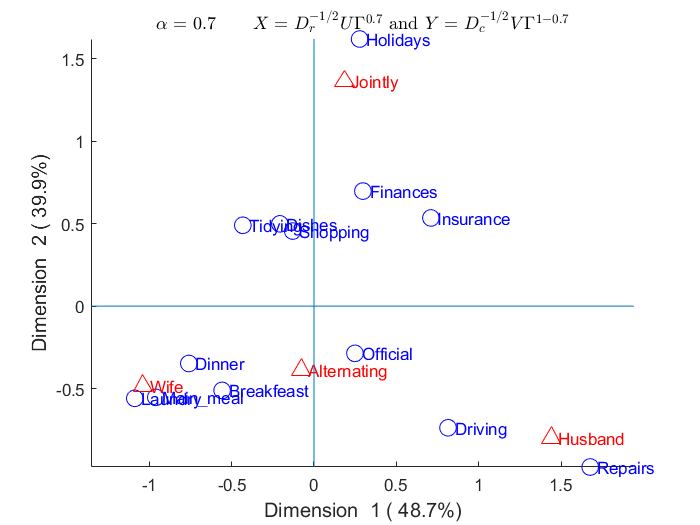

plots.alpha=0.7;
out=CorAna(tableN,'plots',plots);

% Compute the distance between row profiles
% \[
% d^2(row_1, row_2) = \sum{\frac{(row.profile_1 - row.profile_2)^2}{average.profile}}
% \]
% For example the distance between the rows Laundry and Main_meal is equal to:
% \[
% d^2(Laundry, Main\_meal) = \frac{(0.886-0.810)^2}{0.344} +
% \frac{(0.0795-0.131)^2}{0.146} + ... = 0.0368
% \]
disp(sum((out.ProfilesRows(1,:)-out.ProfilesRows(2,:)).^2./(out.c')))

   0.036847874532122



% The squared distance between each row profile and the average row profile
% is given by
dist=zeros(out.I,1);
for i=1:out.I
    dist(i)=(sum((out.ProfilesRows(i,:)-out.c').^2./(out.c')));
end
% The Row inertia is calculated as the row mass multiplied by the squared
% distance between the row and the average row profile:
% \[
%     row.inertia = row.mass * d^2(row)
% \]
% Row inertia
% disp(sum(dist.*out.r))
% disp(out.TotalInertia)

## Dati infortuni

Summary
               Singular_value            Inertia             Accounted_for          Cumulative    
             __________________    ___________________    ___________________    _________________

    dim_1      0.46421569981181      0.215496215951769       0.50212218327281     0.50212218327281
    dim_2     0.313250281113568     0.0981257386177292      0.228640256592807    0.730762439865617
    dim_3     0.218012319156491     0.0475293713039915      0.110746964086301    0.841509403951917
    dim_4     0.194669642240696     0.0378962696101205      0.088301121903633     0.92981052585555
    dim_5     0.135309698812229      0.018308714592656     0.0426606643814144    0.972471190236965
    dim_6    0.0941499710830276    0.00886421705493493     0

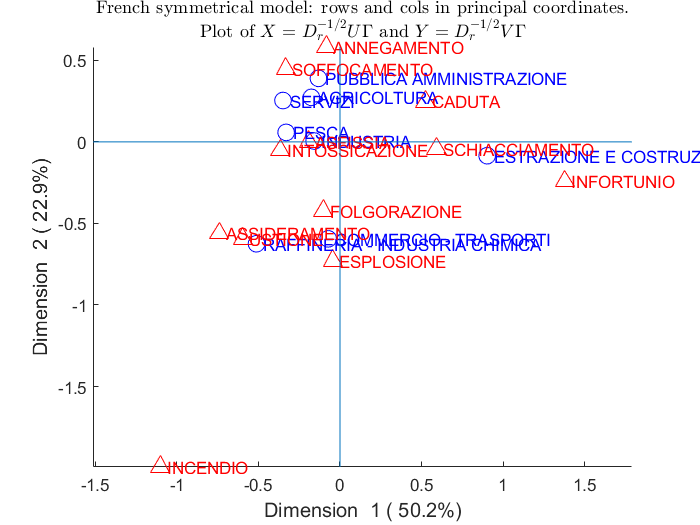

[a, b, raw] = xlsread('D:\research-projects\BRIC2017\analisi_corrispondenze.xlsx','Foglio1','E1:G424');
[tbl,chi2,p,labels]=crosstab(raw(2:end,2),raw(2:end,3));

emptyCells = cellfun(@isempty,labels(:,1));
labels_rows=labels(~emptyCells,1);

emptyCells = cellfun(@isempty,labels(:,2));
labels_columns=labels(~emptyCells,2);

out=CorAna(tbl,'Lr',labels_rows,'Lc',labels_columns);

## CorAna using plots as structure

Input is the contingency table, labels for rows and columns are supplied

Summary
               Singular_value            Inertia             Accounted_for         Cumulative    
             __________________    ____________________    _________________    _________________

    dim_1     0.273421114557299      0.0747591058857557    0.877558731361015    0.877558731361015
    dim_2     0.100085865696555      0.0100171805122288    0.117586535017679    0.995145266378693
    dim_3    0.0203365208395199    0.000413574079856226    0.004854733621307                    1

ROW POINTS
Results for dimension: 1
                              Scores               CntrbPnt2In           CntrbDim2In    
                        ___________________    ___________________    __________________

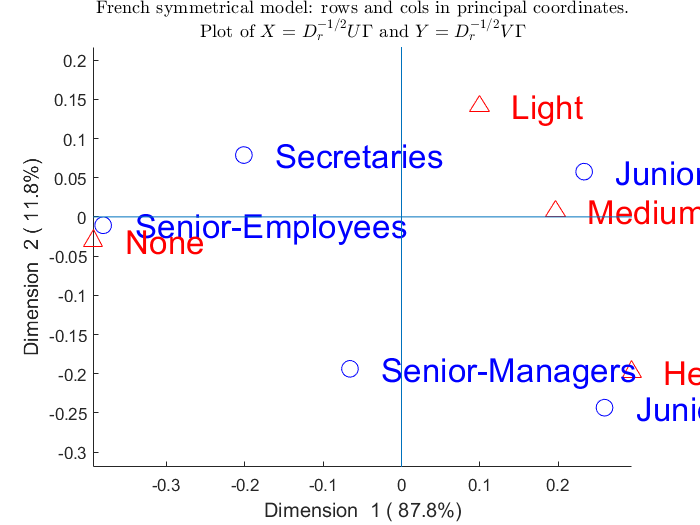

load smoke
plots=struct;
plots.FontSize=20;
N=crosstab(X(:,1),X(:,2));
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'plots',plots);